## Inicia TODO el CoBot para real

clear ur
ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e') %Conectamos ROS de matlab con el cobot

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.22.0.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     1.2482   -1.6446    1.7074   -1.6198   -1.5722   -0.3124


%defase_Robot = 0; %Ve a Y positivo (Lado del cable)
realSense = realsenseSubscriberSO_ARM; %-----------ACTIVAR
defase_Robot = pi; %Ve a Y negativo (Otro lado del cable)

## Limpia la variable de UR en caso de error

clear ur

## Mover al cobot por coordenadas cartesianas

angulogripmin = -pi;
angulogripmax = pi;
x = 0;
y = 0.4;
z = 0.33; %Aqui esta en 0, si el brazo tiene alguna mod, cambiar la altura de +0.18.. en el de cinematica inversa
angulo_Gripper = 1.5708; %con respecto al eje principal del cobot c---g 

coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa] = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles) %Falta la ",ur"

condicion = logical
   1


q =     1.2310
   -1.8429
    1.7905
   -1.5184
   -1.5708
   -0.3398


jointAngles =     1.2310   -1.8429    1.7905   -1.5184   -1.5708   -0.3398


H_Actual_Mesa =     0.0000   -1.0000         0    0.4000
   -1.0000   -0.0000         0   -0.0000
         0         0   -1.0000    0.3300
         0         0         0    1.0000


for n = 1:6
    configuraciones(n).JointPosition = jointAngles(n);
end
show(robot,configuraciones)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


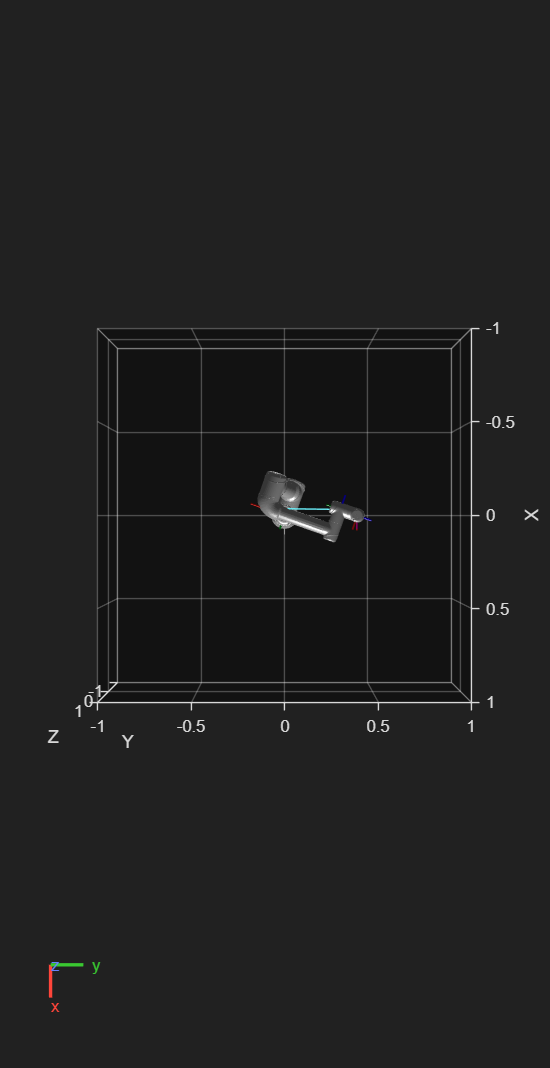

view(90,90)

## Cierra el gripper

actuateGripper(ur,'grip')

## Abre el gripper

actuateGripper(ur,'release')

## Toma una foto

[rgbImg, depthImg,irImage] = fotosw(realSense); %La foto actual es la computern.jpg
imshow(rgbImg)
imshow(depthImg(:,:,3))
imshow(irImage)

# ***%%%%%%%%%%-----------RUTINAS------------%%%%%%%%%%***

## RUTINA DE TOMA DE FOTOS

%Creamos unicamente una lista (matriz) de puntos a los que debera de llegar
%el cobot para tomar fotos y los almacenamos para posteriormente usarlos
h = 0.335;
n = -1;
puntos = []; % Inicializar matriz de puntos

for r = 0.25:0.05:0.65
    n = n + 1;
    for theta = -0.35 : pi/(15 + 2*n) : 0.35 %theta = -pi/2 : pi/(5 + 2*n) : pi/2
        puntos(end+1, :) = [r,theta,h]; % Agregar fila [x y z]
    end
end

% Mostrar los puntos
disp('Lista de puntos generados (filas = puntos):');

Lista de puntos generados (filas = puntos):


disp(puntos);

    0.2500   -0.3500    0.3350
    0.2500   -0.1406    0.3350
    0.2500    0.0689    0.3350
    0.2500    0.2783    0.3350
    0.3000   -0.3500    0.3350
    0.3000   -0.1652    0.3350
    0.3000    0.0196    0.3350
    0.3000    0.2044    0.3350
    0.3500   -0.3500    0.3350
    0.3500   -0.1847    0.3350
    0.3500   -0.0193    0.3350
    0.3500    0.1460    0.3350
    0.3500    0.3114    0.3350
    0.4000   -0.3500    0.3350
    0.4000   -0.2004    0.3350
    0.4000   -0.0508    0.3350
    0.4000    0.0988    0.3350
    0.4000    0.2484    0.3350
    0.4500   -0.3500    0.3350
    0.4500   -0.2134    0.3350
    0.4500   -0.0768    0.3350
    0.4500    0.0598    0.3350
    0.4500    0.1964    0.3350
    0.4500    0.3330    0.3350
    0.5000   -0.3500    0.3350
    0.5000   -0.2243    0.3350
    0.5000   -0.0987    0.3350
    0.5000    0.0270    0.3350
    0.5000    0.1527    0.3350
    0.5000    0.2783    0.3350
    0.5500   -0.3500    0.3350
    0.5500   -0.2336    0.3350
    0.55


% Crear una tabla vacía para guardar las poses con cada foto que tome
columnas = {'base', 'hombro', 'codo', 'w1', 'w2', 'w3'};
% Crear una tabla con tipos de datos predefinidos
Posiciones = table([], [], [], [], [], [], 'VariableNames', columnas);


### Creación de carpeta para fotos

% Ruta de la carpeta donde se guardará la imagen
    folderPath = 'C:\Users\hecto\Documents\0_TEC_DRIVE\8 SEMESTRE\0_COMPETENCIA_BRASIL_RBC\FOTOS';
    % Verificar si la carpeta existe
    if ~exist(folderPath, 'dir')
        mkdir(folderPath);  % Crear la carpeta si no existe
    end

### Iniciamos el programa para que tome fotos

coci =     0.2500   -0.3500    0.3350


Condición de frontera
Condición de cercania


Punto 1: x = 0.250, y = -0.350, z = 0.335


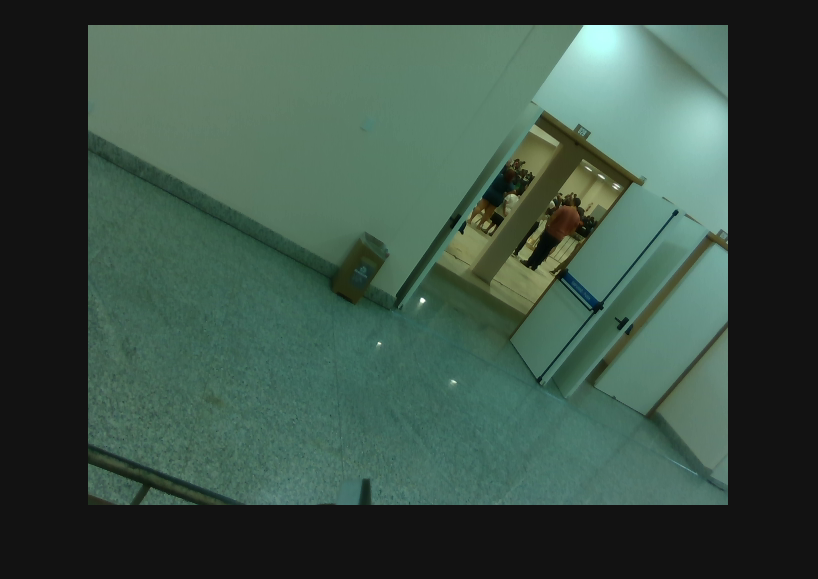

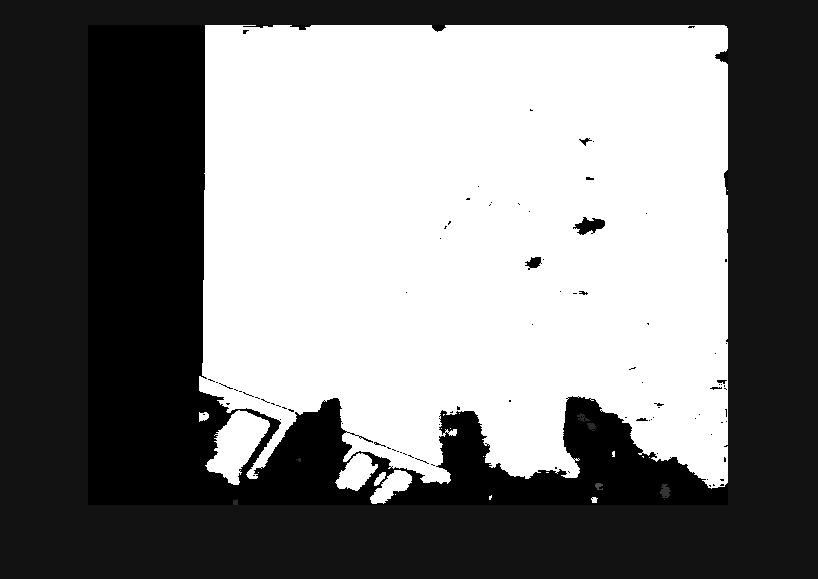

rgbImg = 480×640×3 uint8 array
rgbImg(:,:,1) =

   105   105   102   103   102   100   102   101   101   102   104   104   105   105   103   104   103   102   104   103   104   103   103   103   103   102   101   102   102   102   103   104   106   106   102   102   103   103   103   103   106   106   106   105   103   104   104   106   106   106   106   105   103   104   103   103   104   104   101   102   102   100   101   102   103   103   104   103   103   104   104   104   103   102   105   105   102   100   100   100   106   104   104   106   102   100   101   102   102   102   103   102   102   102   103   104   103   104   104   103   103   104   108   108   106   106   105   106   103   103   103   103   102   101   102   103   102   101   103   104   104   104   103   104   103   103   102   101   102   102   103   102   100   101   100   100   103   105   103   102   102   102   101   101   101   102   101    99   103   103   102   102   102   101   101   103   103   101    

depthImg = depthImg(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

irImage = 480×640 uint8 matrix
   25   25   28   31   27   26   26   25   24   24   24   25   26   26   27   36   41   34   33   32   24   21   20   20   20   20   20   21   21   21   22   22   22   23   22   23   24   27   30   33   34   33   31   31   31   32   32   30   29   26
   26   25   26   28   27   28   29   26   25   24   24   24   25   25   27   35   35   31   39   37   26   23   21   21   20   20   20   21   21   21   21   21   21   22   23   24   25   28   30   33   35   37   36   34   33   32   31   30   28   24
   27   26   25   25   26   29   31   28   26   25   25   24   24   24   25   27   27   29   40   38   27   24   23   23   22   21   21   21   21   21   21   21   22   23   24   25   27   29   29   30   32   34   36   34   33   31   28   26   24   25
   26   27   28   26   26   27   28   27   28   29   26   24   24   24   24   25   24   26   35   36   28   26   25   23   22   22   22   22   22   22   22   23   24   24   25   27   29   30   29   29   29   29   30 

pose =    95.0679  -74.6638   12.0766  -95.7695  -21.1240  -55.9333


coci =     0.2500   -0.1406    0.3350


Condición de frontera
Condición de cercania


angulo_Gripper = 0; %TAMBIEN CAMBIAR EN CASO DE
for i = 1:size(puntos, 1)
    r = puntos(i, 1);
    theta = puntos(i, 2);
    h = puntos(i, 3);
    coci = [r theta h]
    jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur);
    pause(2)
    % Imprimo el punto
    fprintf('Punto %d: x = %.3f, y = %.3f, z = %.3f\n', i, r, theta, h);
    %Toma de fotografía
    [rgbImg, depthImg, irImage] = fotosw(realSense)
    pause(2)
    % Nombre del archivo
    fileName = sprintf('foto_%d.png', i);
    % Ruta completa del archivo
    fullPath = fullfile(folderPath, fileName);
    imwrite(rgbImg, fullPath);  % Guardar la imagen
    rgbFotos{i} = rgbImg;
    profFotos{i} = depthImg;
    irFotos{i} = irImage;
    save('datasetbrasil','rgbFotos','profFotos','irFotos');
    
    %Leemos los valores de la pose
    pose = rad2deg(readJointConfiguration(ur))
    %Almacenamos los valores dentro de las varibles que guardaran los objetos en la tabla
    base = pose(1); hombro = pose(2); codo = pose(3);
    w1 = pose(4); w2 = pose(5); w3 = pose(6);
    %Almacenamos los valores ahora si en la tabla y generamos una nueva fila
    nueva_fila = {base,hombro,codo,w1,w2,w3};
    Posiciones = [Posiciones; nueva_fila];
    %Guardamos la tabla
    save('jntconfigOfPics.mat','Posiciones');
end

## RUTINA DE MEDIDAS

h = 0.35;

coci = car2pol(0,0.3,0.335)

coci =     0.3000    1.5708    0.3350


jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);

Condición de frontera
Condición de cercania


pause(20)

puntos = [0 0.3 h; 0.1 0.3 h; -0.1 0.3 h; -0.1 0.4 h; 0.1 0.4 h; 0.1 0.3 h; 0 0.3 h]
for i=1:1:7
    coci = car2pol(puntos(i,1),puntos(i,2),h)
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

# ***%%%%%%%%%%-----EXTRAS-----%%%%%%%%%%***

## Creacion de objeto virtual (Prueba)

robot = loadrobot("universalUR5e");
configuraciones = robot.homeConfiguration;

## Uso de objeto virtual (Prueba)

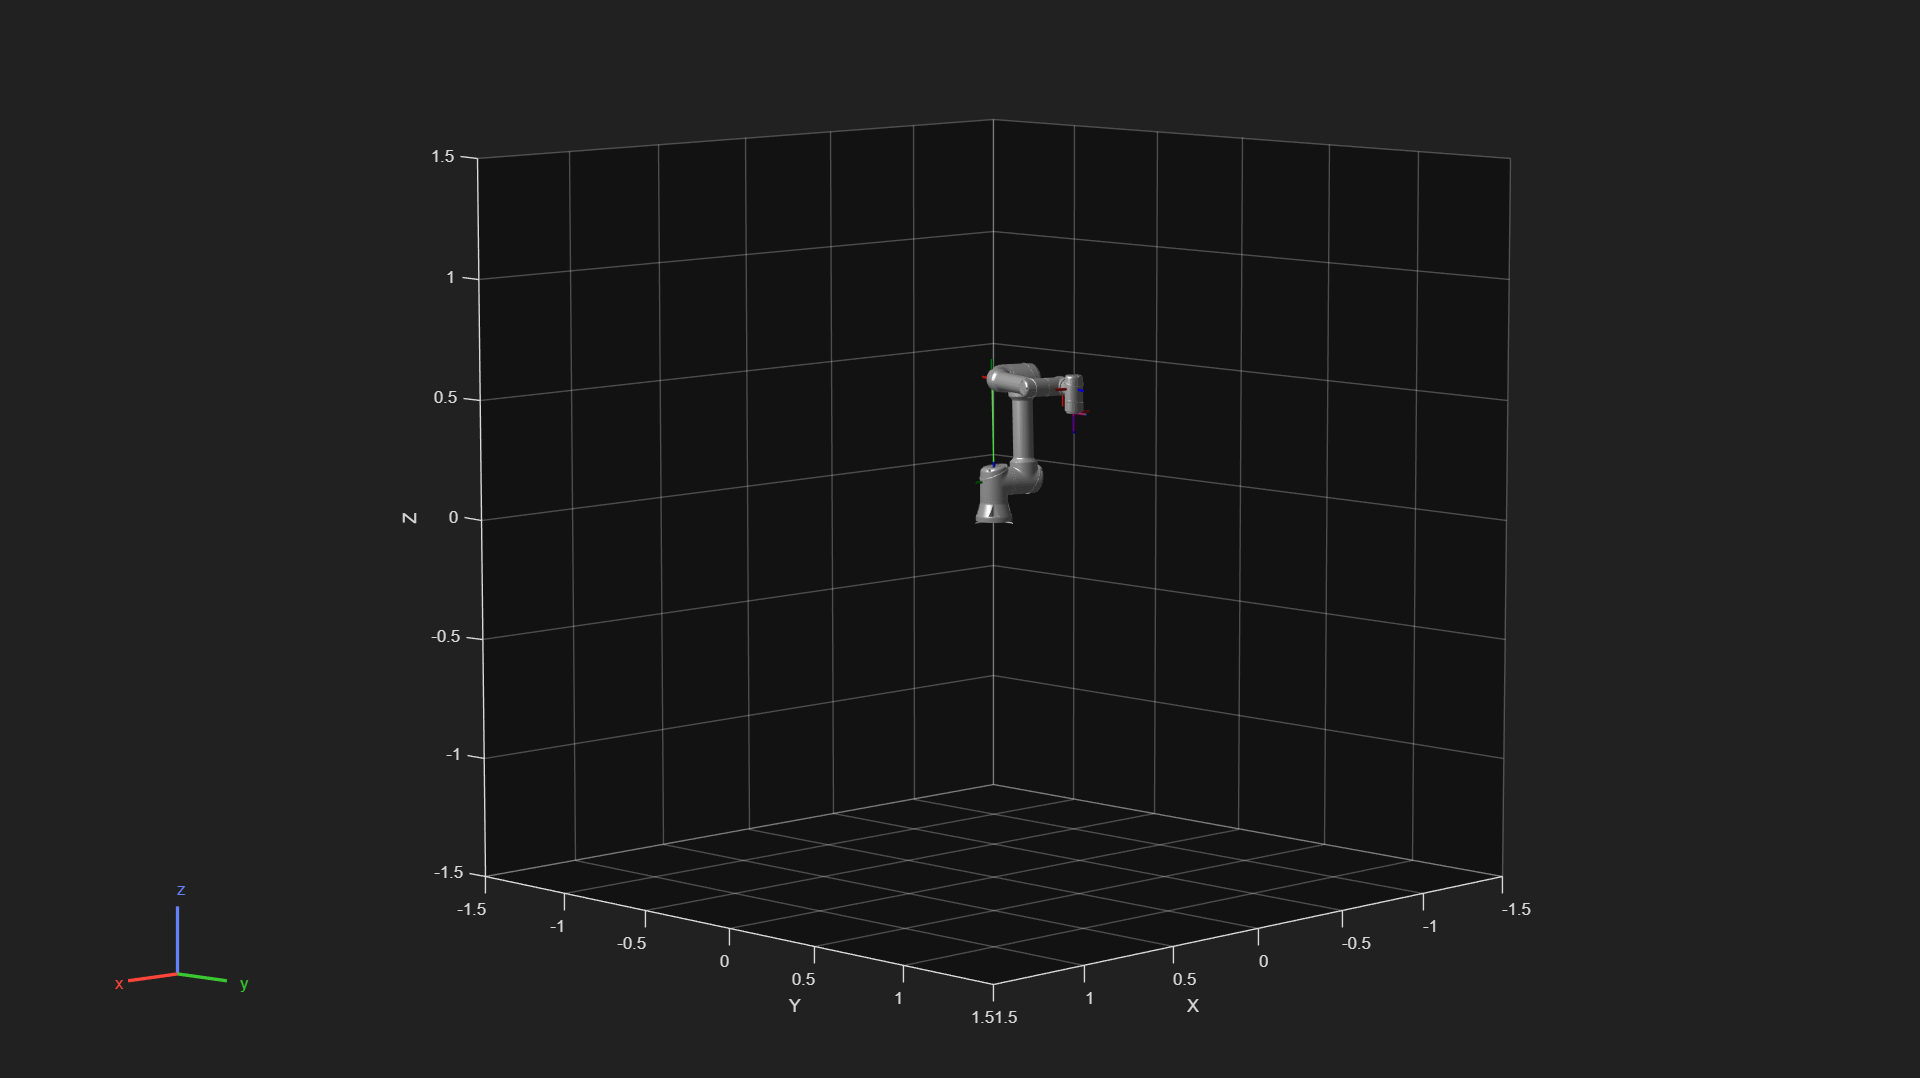

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


for n = 1:6
    configuraciones(n).JointPosition = jointAngles(n);
end
show(robot,configuraciones)
view(90,90)